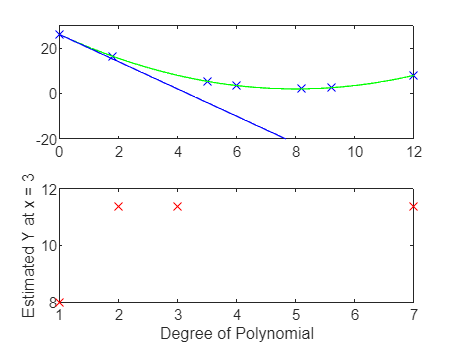

%Question 1
figure;
x = [0 1.8 5 6 8.2 9.2 12];
y = [26 16.415 5.375 3.5 2.015 2.54 8];
title('Interpolating Polynomials')
subplot(2, 1, 1);
plot(x, y, 'bx');
hold on;
M = [
    x(1)^6 x(1)^5 x(1)^4 x(1)^3 x(1)^2 x(1)^1 1; 
    x(2)^6 x(2)^5 x(2)^4 x(2)^3 x(2)^2 x(2)^1 1;  
    x(3)^6 x(3)^5 x(3)^4 x(3)^3 x(3)^2 x(3)^1 1; 
    x(4)^6 x(4)^5 x(4)^4 x(4)^3 x(4)^2 x(4)^1 1; 
    x(5)^6 x(5)^5 x(5)^4 x(5)^3 x(5)^2 x(5)^1 1; 
    x(6)^6 x(6)^5 x(6)^4 x(6)^3 x(6)^2 x(6)^1 1; 
    x(7)^6 x(7)^5 x(7)^4 x(7)^3 x(7)^2 x(7)^1 1
    ];
r = y';
a = M\r;
X = linspace(0, 12);
Y = a(1)*X.^6 + a(2)*X.^5 + a(3)*X.^4 + a(4)*X.^3 + a(5)*X.^2 + a(6)*X + a(7);
YC = a(4)*X.^3 + a(5)*X.^2 + a(6)*X + a(7);
YQ = a(5)*X.^2 + a(6)*X + a(7);
YL = a(6)*X + a(7);

plot(X, Y, 'r');
plot(X, YC, 'k');
plot(X, YQ, 'g');
plot(X, YL, 'b');
ylim([-20, 30]);


subplot(2,1,2);
xlim([1, 7]);
ylim([11.2, 12.4]);
Y = a(1)*3.^6 + a(2)*3.^5 + a(3)*3.^4 + a(4)*3.^3 + a(5)*3.^2 + a(6)*3 + a(7);
YC = a(4)*3.^3 + a(5)*3.^2 + a(6)*3 + a(7);
YQ = a(5)*3.^2 + a(6)*3 + a(7);
YL = a(6)*3 + a(7);


plot(7, Y, 'rx'); ylabel('Estimated Y at x = 3'); xlabel('Degree of Polynomial');
hold on;
plot(3, YC, 'rx');
plot(2, YQ, 'rx');
plot(1, YL, 'rx');
hold off;


%degree = x axis
%%y estimation at x =3

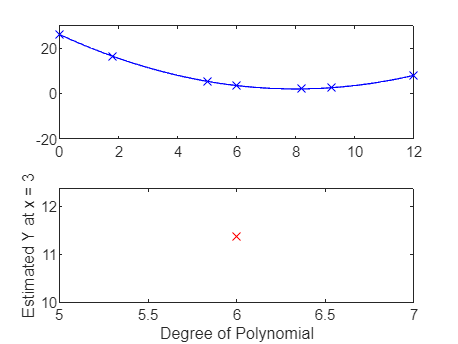

%EXEMPLARY CODE
figure;
clear;
x = [0 1.8 5 6 8.2 9.2 12];
y = [26 16.415 5.375 3.5 2.015 2.54 8];
title('Interpolating Polynomials')
subplot(2, 1, 1);
plot(x, y, 'bx');
hold on;

degree = 6; % Set the degree of the polynomial
a = polyfit(x, y, degree); % Use polyfit to fit a polynomial of the specified degree

X = linspace(0, 12);
Y = polyval(a, X);
YC = polyval(a, X, degree-1);
YQ = polyval(a, X, degree-2);
YL = polyval(a, X, degree-3);

plot(X, Y, 'r');
plot(X, YC, 'k');
plot(X, YQ, 'g');
plot(X, YL, 'b');
ylim([-20, 30]);

subplot(2, 1, 2);
xlim([1, 7]);
ylim([11.2, 12.4]);

x_estimation = 3; % Estimation point
Y = polyval(a, x_estimation);
YC = polyval(a, x_estimation, degree-1);
YQ = polyval(a, x_estimation, degree-2);
YL = polyval(a, x_estimation, degree-3);

plot(degree, Y, 'rx');
ylabel('Estimated Y at x = 3');
xlabel('Degree of Polynomial');
hold off;

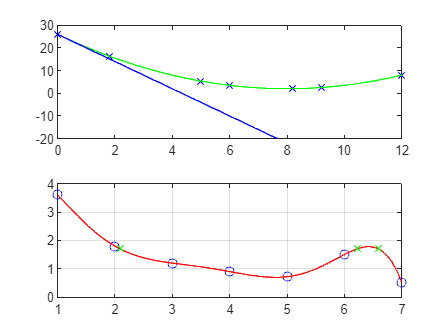

%Question 4
clear;
x = 1:7;
y = [3.6 1.8 1.2 .9 .72 1.5 .51429];

plot(x, y, 'bo');
hold on; grid on;

M = [
    x(1)^6 x(1)^5 x(1)^4 x(1)^3 x(1)^2 x(1)^1 1; 
    x(2)^6 x(2)^5 x(2)^4 x(2)^3 x(2)^2 x(2)^1 1;  
    x(3)^6 x(3)^5 x(3)^4 x(3)^3 x(3)^2 x(3)^1 1; 
    x(4)^6 x(4)^5 x(4)^4 x(4)^3 x(4)^2 x(4)^1 1; 
    x(5)^6 x(5)^5 x(5)^4 x(5)^3 x(5)^2 x(5)^1 1; 
    x(6)^6 x(6)^5 x(6)^4 x(6)^3 x(6)^2 x(6)^1 1; 
    x(7)^6 x(7)^5 x(7)^4 x(7)^3 x(7)^2 x(7)^1 1
    ];

r = y';
a = M\r;

X = linspace(1, 7);

Y = a(1)*X.^6 + a(2)*X.^5 + a(3)*X.^4 + a(4)*X.^3 + a(5)*X.^2 + a(6)*X + a(7);

plot(X, Y, 'r');

SelectY = 1.7;

a(7) = a(7) - SelectY;
j = [a];
r = roots(j);

plot(r(1), SelectY, 'gx');
plot(r(2), SelectY, 'gx');
plot(r(5), SelectY, 'gx');

%Question 5

%Question 6
x = linspace(-1, 1, 10);
y = 1 ./ (1+(25*x.^2));

plot(x, y, 'or');
xlim([-1, 1]);
ylim([0, 1]);
hold on; grid on;

xfit = linspace(-1, 1);
yfit = spline(x, y, xfit);
plot(xfit, yfit, '-b');

%Question 7

% Sample data (replace this with your actual data)
x = [0 2 4 7 10 12];
y = [20 20 12 7 6 6];

% Define x-value for estimation
x_estimate = 1.5;

% Perform not-a-knot spline interpolation
not_a_knot_spline = spline(x, y);
y_estimate_not_a_knot = ppval(not_a_knot_spline, x_estimate);

% Perform clamped spline interpolation with first derivatives set to 0
clamped_spline = spline(x, [0, y, 0]);
y_estimate_clamped = ppval(clamped_spline, x_estimate);

% Plotting
x_vals = linspace(0, 12, 100);
plot(x, y, 'o', x_vals, ppval(not_a_knot_spline, x_vals), '-', x_vals, ppval(clamped_spline, x_vals), '--')
legend('Data Points', 'Not-a-Knot Spline', 'Clamped Spline');
xlabel('x');
ylabel('y');
title('Spline Interpolation');
grid on;

fprintf('Estimated y (not-a-knot) at x = %.2f: %.2f\n', x_estimate, y_estimate_not_a_knot);
fprintf('Estimated y (clamped) at x = %.2f: %.2f\n', x_estimate, y_estimate_clamped);

%Question 8